# (9). Import and visualise 3D HNCA spectrum

### Introduction

While 1D and 2D NMR techniques have been instrumental in elucidating molecular structures, they have limitations when it comes to studying large, complex molecules like proteins, nucleic acids, and large organic compounds. The increasing complexity of these molecules often leads to overcrowded and overlapping spectra in 1D and 2D NMR, making it challenging to resolve and interpret individual spectral features. 3D NMR emerged as a solution to this problem, providing a third dimension of spectral data that significantly enhances resolution and aids in the unambiguous assignment of spectral peaks.

In 3D NMR, three frequency axes are used instead of the one or two axes in 1D and 2D NMR, respectively. This is achieved by adding an extra dimension of data acquisition to the traditional NMR experiment, which allows for the correlation between three different types of nuclear interactions. Each dimension in a 3D NMR experiment can represent a different type of NMR interaction, such as chemical shift, J-coupling, or Nuclear Overhauser Effect (NOE), depending on the specific 3D NMR experiment being conducted. The result is a data cube, rather than a data matrix (as in 2D NMR), which can be processed and analyzed to extract detailed structural information.

3D NMR spectroscopy is particularly vital in the study of proteins and other biopolymers. It enables researchers to determine the three-dimensional structures of these molecules in solution, providing insights into their function, dynamics, and interactions. This is crucial for understanding biological processes at the molecular level and has applications in drug design, where the detailed knowledge of molecular structures is essential for developing new therapeutics.

### **HNCA **

In this example we will import and visualize 3D HNCA (Hydrogen, Nitrogen, Carbon-Alpha) spectrum of [GB1](https://www.rcsb.org/structure/2j52) (B1 domain of protein G). One of the initial steps of protein structure determination is backbone assignment through triple resonance experiments, which correlate the signals of 1H, 13C and 15N in the backbone. Such experiments are named after their magnetization transfer paths: for example, HNCA moves the magnetization from the amide proton H of the peptide bond to the nearby 15N nucleus, then onwards to the two 13CA nuclei up and down the amino acid chain, and then (for detection sensitivity reasons) back to the amide proton

The individual amino acids in the backbone of the protein, often called **residues** will give rise to signals in the spectra. Since these residues are sequentially connected in the backbone one can travel from one peak to another in our 3D spectrum, connecting our residues. Once the peaks are connected one can use the chemical shifts of the peaks (the position in our 3D spectra, where each axis represents the 1H,13C,15N chemical shift) and prior information to assign the protein. For large proteins this is difficult because hundreds of amino acids in the backbone will cause overcrowding, hence the processing of the spectra is especially important to make distinct peaks.

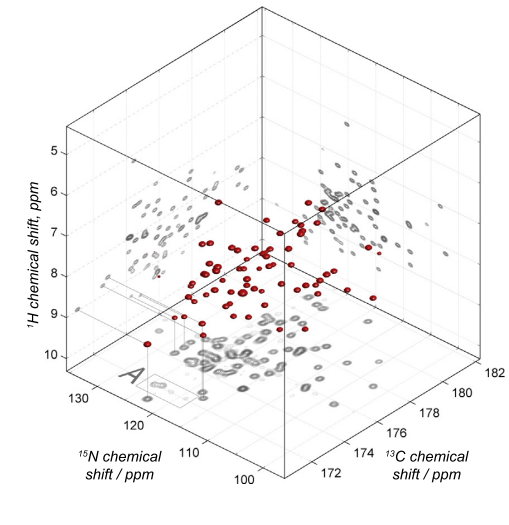           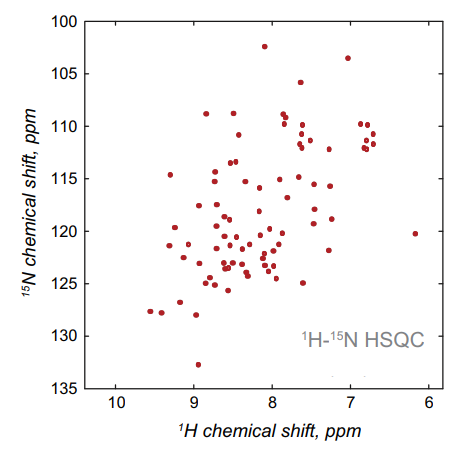

(*Quantum mechanical NMR simulation algorithm for protein-size spin systems L.Edwards,D.Savostyanov, Z. Welderufael, D. Lee, I.Kuprov*)

Above you can see an illustration of a 3D HNCA spectra for ubiquitin. Visualizing and working with the spectra is difficult and very often we select 2D slices from the 3D spectra to view the individual signals. 

### **Experimental data import **

In this example, the 3D spectra of GB1 has already been converted into a MATLAB matrix in the frequency spectrum and can be easily loaded in. This NMR data is kindly provided by Prof. Ilya Kuprov, University of Southampton.

% Filename of the HNCA data to be loaded and visualized
dataFileName = 'HNCA_GB1_Phase.mat';

% Load 3D HNCA GB1 spectrum from the specified file
load(dataFileName, 'c_ax_ppm', 'h_ax_ppm', 'n_ax_ppm', 'data');


### **Visualization with a MATLAB interactive tool**

Before we can embark on processing the spectra, we first need to be able to view it. This can achieved by running the code called **Visualizing_HNCA.m. **

The matrix holding the spectra only contains the raw intensities in a 3D matrix. The peaks are visualised by selecting a slice in one of the dimensions and interpreted similar to a 2D spectra. In the script you are able to interactively view any slice of the cube in the 1H-13C dimension to see the individual residues. The slice can be selected by pressing the 15N position in the figure on the top right corner. The figure is showing at which positions of the 15N dimensions we have the most intense signals. When you have selected a nitrogen dimension a red line will show the current position and the 1H-13C 2D slice will be seen in the central panel.

To change the position of the slice press the "SPACE" key on your keyboard and reselect the 15N position. You can click on any peak in the slice to zoom in and view the signal.

% Call the Visualizing_HNCA function to visualize the loaded data
Visualizing_HNCA(dataFileName);

Error using ginput (line 84)
Interrupted by figure deletion

Error in Visualizing_HNCA (line 71)
        [h_ppm, c_ppm] = ginput(1);

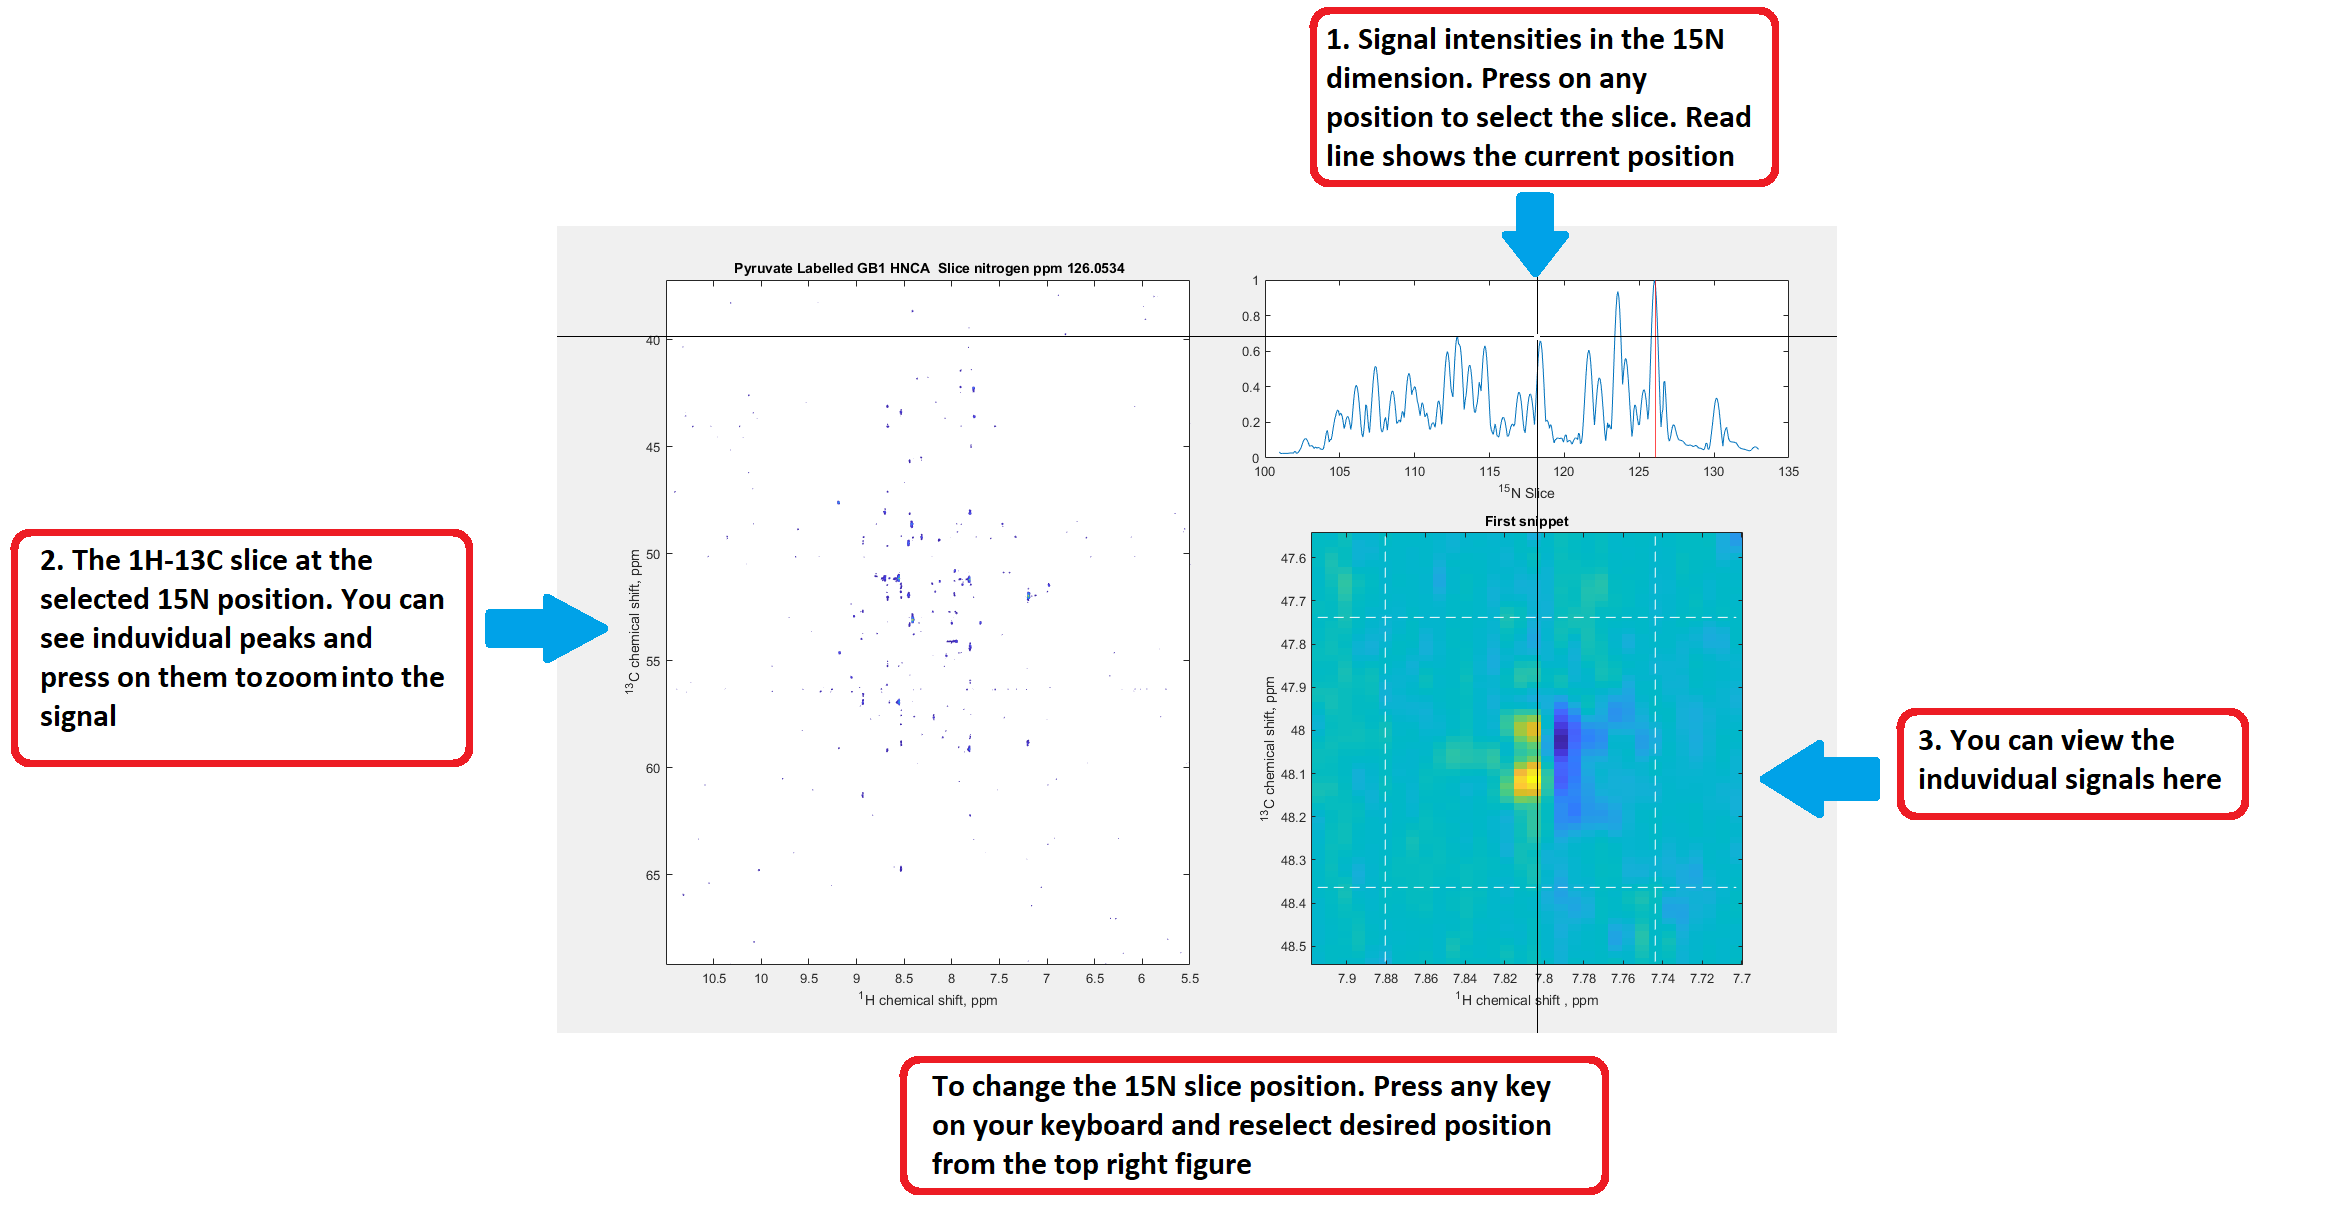

### **Summary **

3D NMR experiments have been introduced and we discussed how they can be used to study large biomolecular structures. This is especially important in the analysis of large proteins which contain many amino acids, whose signals in standard 1D and 2D experiments would cause crowding and overlap. The extension of the experiment into the third dimension allows one to encode more information. In this tutorial the HNCA spectra was imported and its use in  protein backbone assignment briefly outlined. Visualisation of 3D spectra can be difficult. We have shown how this can be roughly done with three dimensional surface plots. However, more commonly 2D slices at particular dimensions are extracted and analysed as if a 2D spectra.